% 检查每个子树的分类错误
% 未修剪的决策树倾向于过度拟合。平衡模型复杂性和样本外性能的一种方法是修剪树（或限制其增长），
% 以便样本内和样本外性能令人满意。
% Examine the Classification Error for Each Subtree
% Unpruned decision trees tend to overfit. One way to balance model complexity
% and out-of-sample performance is to prune a tree (or restrict its growth) 
% so that in-sample and out-of-sample performance are satisfactory.

## 加载 Fisher 鸢尾花数据集。将数据划分为训练 (50%) 和验证 (50%) 集。

Load Fisher's iris data set. Partition the data into training (50%) and validation (50%) sets.

load fisheriris
n = size(meas,1);
rng(1) % 为了重现性 For reproducibility
idxTrn = false(n,1);
idxTrn(randsample(n,round(0.5*n))) = true; % 训练集逻辑索引 Training set logical indices 
idxVal = idxTrn == false;                  % 验证集逻辑索引 Validation set logical indices

## 使用训练集生成分类树

Grow a classification tree using the training set.

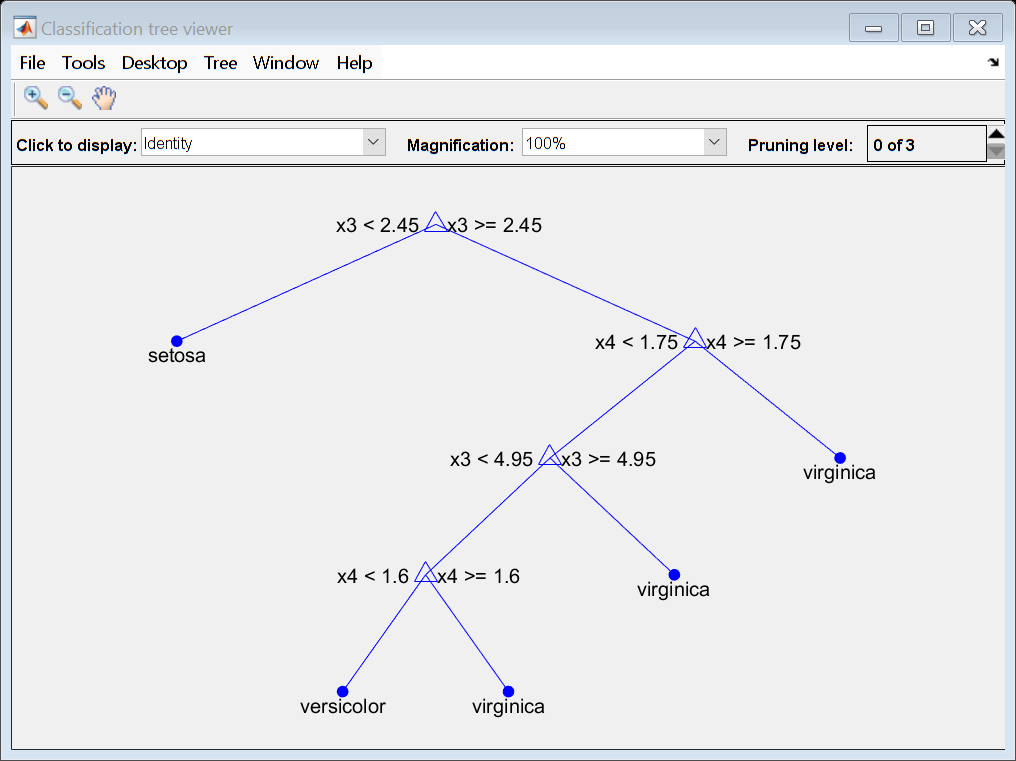

Mdl = fitctree(meas(idxTrn,:),species(idxTrn));

% 查看分类树。
% View the classification tree.
view(Mdl,'Mode','graph');

% 分类树有四个修剪级别。
% 级别 0 是完整的、未修剪的树
% 级别 3 只是根节点（即没有分裂）
% The classification tree has four pruning levels. Level 0 is the full, 
% unpruned tree (as displayed). Level 3 is just the root node (i.e., no splits).

## 检查除最高级别之外的每个子树（或修剪级别）的训练样本分类错误。

Examine the training sample classification error for each subtree (or pruning level) excluding the highest level.

m = max(Mdl.PruneList) - 1;
trnLoss = resubLoss(Mdl,'SubTrees',0:m)

trnLoss =     0.0267
    0.0533
    0.3067



% 完整的、未修剪的树错误分类了大约 2.7% 的训练观察结果。
% 修剪到 1 级的树错误分类了大约 5.3% 的训练观察结果。
% 修剪到 2 级（即树桩）的树错误分类了大约 30.6% 的训练观察结果。
%
% 检查除最高级别之外的每个级别的验证样本分类错误。
% The full, unpruned tree misclassifies about 2.7% of the training observations.
% The tree pruned to level 1 misclassifies about 5.3% of the training observations.
% The tree pruned to level 2 (i.e., a stump) misclassifies about 30.6% of the training observations.
% 
% trnLoss =
%     0.0267
%     0.0533
%     0.3067

## 检查除最高级别之外的每个级别的验证样本分类错误。

Examine the validation sample classification error at each level excluding the highest level.

valLoss = loss(Mdl,meas(idxVal,:),species(idxVal),'SubTrees',0:m)

valLoss =     0.0369
    0.0237
    0.3067


% 完整的、未修剪的树错误分类了大约 3.7% 的验证观察。
% 修剪到 1 级的树错误分类了大约 2.4% 的验证观察。
% 修剪到 2 级（即树桩）的树错误分类了大约 30.7% 的验证观察。
% The full, unpruned tree misclassifies about 3.7% of the validation observations.
% The tree pruned to level 1 misclassifies about 2.4% of the validation observations.
% The tree pruned to level 2 (i.e., a stump) misclassifies about 30.7% of the validation observations.
% valLoss =
%     0.0369
%     0.0237
%     0.3067

## 为了平衡模型复杂性和样本外性能，请考虑将 Mdl 修剪到级别 1

To balance model complexity and out-of-sample performance, consider pruning Mdl to level 1.

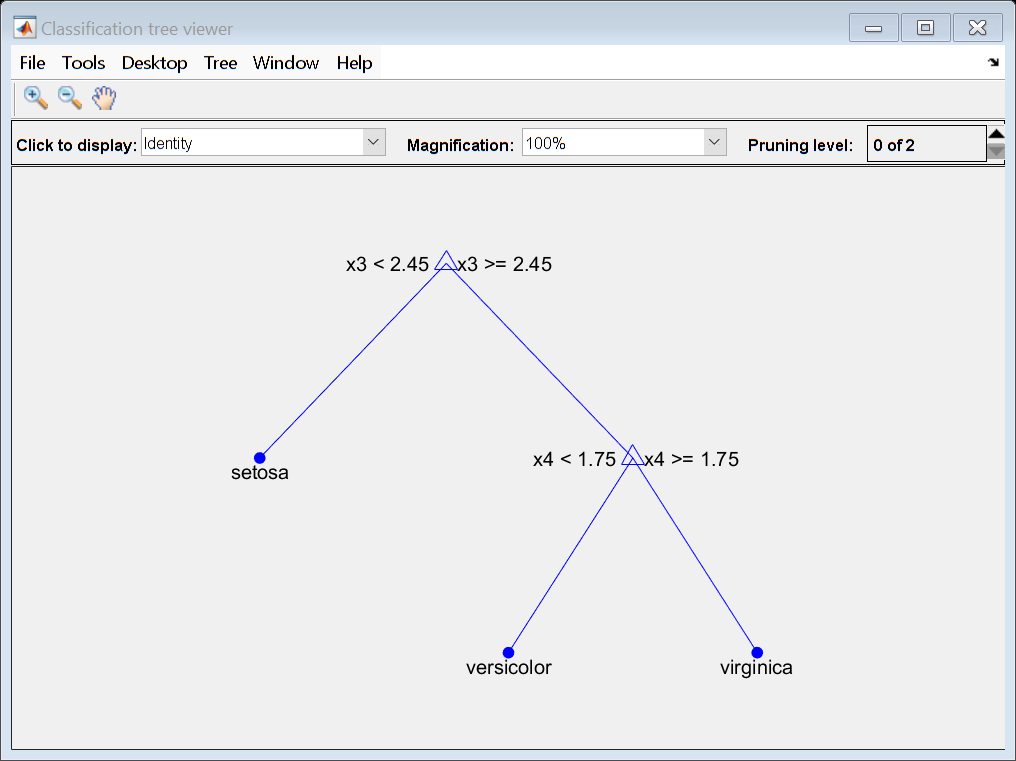

pruneMdl = prune(Mdl,'Level',1);
view(pruneMdl,'Mode','graph')